# **Calculations for Motor sizing dependent on the Lead Screw available **

### 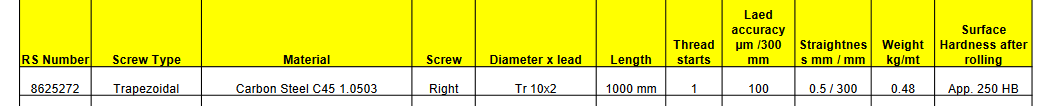

lead = 2 %mm

lead = 2

Diameter = 10 %mm

Diameter = 10

Radius = 0.005 %m

Radius = 0.0050

Circumference = pi*Diameter %mm

Circumference = 31.4159

lead_angle = atand(lead/Circumference)

lead_angle = 3.6426

LiftingMass = 5 %kg

LiftingMass = 5

G=9.81 %m/s^2

G = 9.8100

friction_coefficient = 0.3 

friction_coefficient = 0.3000

To find the Torque, which our Motor has to supply we derive from Torque=Force*Distance, where the distance is the radius of the lead screw and the force the force of the load divided by the mechanical advantage gained through the lead screw.  

% Torque = Force*Radius 
% Force = ForceLoad/MA

ForceLoad = LiftingMass*G 

ForceLoad = 49.0500

The Mechanical Advantage MA is the product of Velocity Ratio and Effiency dependent on the lead 

angle.

%MA=VR*E

%Velocity Ratio = circumference/lead shows rotation for 1mm height gain
VR=Circumference/lead

VR = 15.7080

Efficiency shows the impact of friction on the system, which can be accounted for as as increase in angle and then therefor the ratio between angle and friction angle.

%E=tand(a)/tand(a+b) a=lead_angle, b=friction_angle
friction_angle= atand(friction_coefficient)

friction_angle = 16.6992


E=(tand(lead_angle))/(tand(lead_angle+friction_angle))

E = 0.1717


MA=VR*E

MA = 2.6973

With all values found we conclude 

Force=ForceLoad/MA %N

Force = 18.1849

Torque=Force*Radius %Nm

Torque = 0.0909

Therefore we know to choose motors with a torque of at least 10N/Cm

KgM =Torque / G

KgM = 0.0093

KgCm=KgM*100

KgCm = 0.9269